# **4. MEASURING WELLBEING**

## **PART 4.1**

% start fresh
clc, clearvars, close all

% import data set
tempdata1 = readtable('Download-GDPconstant-USD-countries.xlsx', Sheet = 'Download-GDPconstant-USD-countr', ReadVariableNames = true, VariableNamingRule = 'preserve', TextType='string');
tempdata1

tempdata1 = 3685×55 table
    CountryID       Country                                             IndicatorName                                              1970          1971          1972          1973          1974          1975          1976          1977          1978          1979          1980          1981          1982          1983          1984          1985          1986          1987          1988          1989          1990          1991          1992          1993          1994          1995

% filter to get only final consumption expenditure
tempdata2 = tempdata1(tempdata1.IndicatorName == 'Final consumption expenditure', :);

% get number of nonmissing values
tempdata2.NumAvailable = NaN(height(tempdata2), 1);
for i = 1:height(tempdata2)
    tempdata2(i, :).NumAvailable = sum(~ismissing(tempdata2(i, :))) - 3;
end

% create frequency table
freq_table = tempdata2(:, {'Country' 'NumAvailable'});
disp(freq_table);

                  Country                   NumAvailable
    ____________________________________    ____________

    "Afghanistan"                                52     
    "Albania"                                    52     
    "Algeria"                                    52     
    "Andorra"                                    52     
    "Angola"                                     52     
    "Anguilla"                                   52     
    "Antigua and Barbuda"                        52     
    "Argentina"                                  52     
    "Armenia"                                    32     
    "Aruba"                                      52     
    "Australia"                                  52     
    "Austria"                                    52     
    "Azerbaijan"                                 32     
    "Bahamas"                                    52     
    "Bahrain"      

% get number of countries with no missing value
full_data = sum(tempdata2.NumAvailable == 52);
fprintf('number of countries with complete data: %i', full_data);

number of countries with complete data: 179

% calculate net exports for three countries
nx_afg = table2array(tempdata1(tempdata1.Country == 'Afghanistan' & tempdata1.IndicatorName == 'Exports of goods and services', 4:55) ...
                     - tempdata1(tempdata1.Country == 'Afghanistan' & tempdata1.IndicatorName == 'Imports of goods and services', 4:55));
nx_alb = table2array(tempdata1(tempdata1.Country == 'Albania' & tempdata1.IndicatorName == 'Exports of goods and services', 4:55) ...
                     - tempdata1(tempdata1.Country == 'Albania' & tempdata1.IndicatorName == 'Imports of goods and services', 4:55));
nx_alg = table2array(tempdata1(tempdata1.Country == 'Algeria' & tempdata1.IndicatorName == 'Exports of goods and services', 4:55) ...
                     - tempdata1(tempdata1.Country == 'Algeria' & tempdata1.IndicatorName == 'Imports of goods and services', 4:55));

% create table to show net exports per year
years = linspace(1970, 2021, 52);
net_exports = table(years.', nx_afg.', nx_alb.', nx_alg.', 'VariableNames', {'Year' 'NX | Afghanistan' 'NX | Albania' 'NX | Algeria'});
disp(net_exports);

    Year    NX | Afghanistan    NX | Albania    NX | Algeria
    ____    ________________    ____________    ____________

    1970      -7.5729e+06        1.5048e+08      9.6398e+09 
    1971      -3.6934e+07        1.5647e+08      5.6189e+09 
    1972      -5.8354e+06        1.6319e+08      1.1054e+10 
    1973       4.1908e+07        1.6892e+08       9.454e+09 
    1974       4.9132e+07        1.7592e+08      8.8601e+08 
    1975       2.8852e+07        1.8511e+08     -1.4469e+08 
    1976       5.8943e+07        1.8734e+08      9.4891e+08 
    1977       4.3021e+05        1.9871e+08     -2.4388e+09 
    1978      -2.5757e+07        2.1548e+08     -3.0285e+09 
    1979      -2.2604e+06        1.9327e+08      6.6783e+08 
    1980      -1.0392e+07        2.3653e+08      -3.155e+09 
    1981      -1.2794e+07        2.7251e+08     -6.9545e+09 
    1982 

% filter to get relevant data for two countries
tempdata3 = tempdata1((tempdata1.Country == 'Afghanistan' | tempdata1.Country == 'Albania') ...
                       & (tempdata1.IndicatorName == 'Household consumption expenditure (including Non-profit institutions serving households)' ...
                       | tempdata1.IndicatorName == 'General government final consumption expenditure' ...
                       | tempdata1.IndicatorName == 'Gross capital formation'), :);
% append net exports
tempdata3(end + 1, :) = tempdata3(1, :);
tempdata3(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata3(end, 4:55) = array2table(nx_afg);
tempdata3(end + 1, :) = tempdata3(4, :);
tempdata3(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata3(end, 4:55) = array2table(nx_alb);

% get values in billions and sort according to id
tempdata3(:, 4:55) = tempdata3(:, 4:55) ./ 1e9;
tempdata3 = sortrows(tempdata3, 'CountryID');
tempdata3

tempdata3 = 8×55 table
    CountryID       Country                                             IndicatorName                                              1970         1971          1972         1973        1974        1975        1976         1977         1978          1979         1980         1981          1982         1983         1984         1985        1986         1987          1988          1989          1990         1991         1992        1993        1994        1995        1996

% get indicator names as columns and years as rows
tempdata4 = array2table(transpose(table2array(tempdata3(:, 4:55))), ...
                        'VariableNames', {'C_Afghanistan', 'G_Afghanistan', 'I_Afghanistan', 'NX_Afghanistan', ...
                        'C_Albania', 'G_Albania', 'I_Albania', 'NX_Albania', });
tempdata4

tempdata4 = 52×8 table
    C_Afghanistan    G_Afghanistan    I_Afghanistan    NX_Afghanistan    C_Albania    G_Albania    I_Albania    NX_Albania
    _____________    _____________    _____________    ______________    _________    _________    _________    __________

       2.7342           0.32888          1.6546          -0.0075729       1.9525      0.088309      0.80053      0.15048  
       2.6144           0.33753          1.7649           -0.036934       2.0309      0.091872      0.83218      0.15647  
       2.5292           0.35301          1.6158          -0.0058354       2.1125       0.09555      0.86529      0.16319  
       2.7249           0.37042          1.5661            0.041908       2.1963      0.0

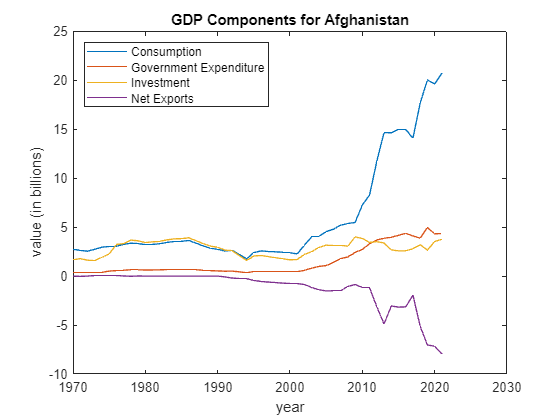

% plot GDP components for afghanistan
plot(years, tempdata4.C_Afghanistan);
hold on;
plot(years, tempdata4.G_Afghanistan);
plot(years, tempdata4.I_Afghanistan);
plot(years, tempdata4.NX_Afghanistan);
title('GDP Components for Afghanistan');
xlabel('year');
ylabel('value (in billions)');
hold off;
legend('Consumption', 'Government Expenditure', 'Investment', 'Net Exports', 'Location', 'northwest');

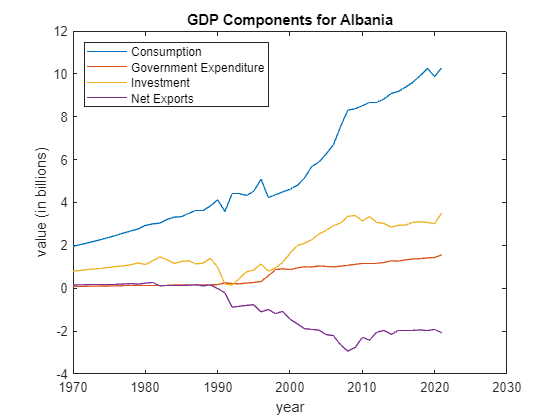

% plot GDP components for albania
plot(years, tempdata4.C_Albania);
hold on;
plot(years, tempdata4.G_Albania);
plot(years, tempdata4.I_Albania);
plot(years, tempdata4.NX_Albania);
title('GDP Components for Albania');
xlabel('year');
ylabel('value (in billions)');
hold off;
legend('Consumption', 'Government Expenditure', 'Investment', 'Net Exports', 'Location', 'northwest');

% calculate GDP components as proportions for both countries
tempdata4.CP_Afghanistan = tempdata4.C_Afghanistan ./ sum(tempdata4{:, 1:4}, 2);
tempdata4.GP_Afghanistan = tempdata4.G_Afghanistan ./ sum(tempdata4{:, 1:4}, 2);
tempdata4.IP_Afghanistan = tempdata4.I_Afghanistan ./ sum(tempdata4{:, 1:4}, 2);
tempdata4.NXP_Afghanistan = tempdata4.NX_Afghanistan ./ sum(tempdata4{:, 1:4}, 2);
tempdata4.CP_Albania = tempdata4.C_Albania ./ sum(tempdata4{:, 5:8}, 2);
tempdata4.GP_Albania = tempdata4.G_Albania ./ sum(tempdata4{:, 5:8}, 2);
tempdata4.IP_Albania = tempdata4.I_Albania ./ sum(tempdata4{:, 5:8}, 2);
tempdata4.NXP_Albania = tempdata4.NX_Albania ./ sum(tempdata4{:, 5:8}, 2);
tempdata4

tempdata4 = 52×16 table
    C_Afghanistan    G_Afghanistan    I_Afghanistan    NX_Afghanistan    C_Albania    G_Albania    I_Albania    NX_Albania    CP_Afghanistan    GP_Afghanistan    IP_Afghanistan    NXP_Afghanistan    CP_Albania    GP_Albania    IP_Albania    NXP_Albania
    _____________    _____________    _____________    ______________    _________    _________    _________    __________    ______________    ______________    ______________    _______________    __________    _________

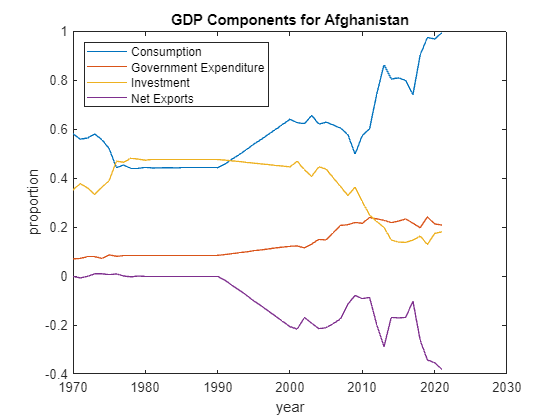

% plot GDP components' proportions for afghanistan
plot(years, tempdata4.CP_Afghanistan);
hold on;
plot(years, tempdata4.GP_Afghanistan);
plot(years, tempdata4.IP_Afghanistan);
plot(years, tempdata4.NXP_Afghanistan);
title('GDP Components for Afghanistan');
xlabel('year');
ylabel('proportion');
hold off;
legend('Consumption', 'Government Expenditure', 'Investment', 'Net Exports', 'Location', 'northwest');

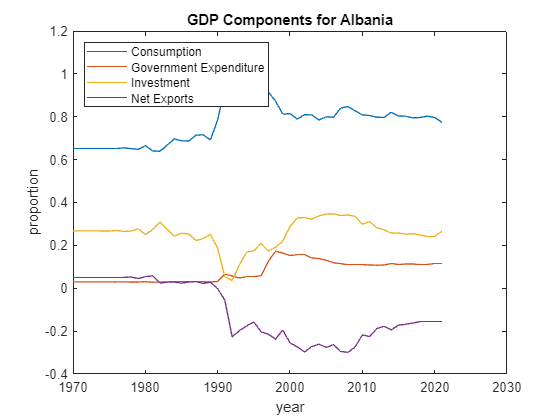

% plot GDP components' proportions for albania
plot(years, tempdata4.CP_Albania);
hold on;
plot(years, tempdata4.GP_Albania);
plot(years, tempdata4.IP_Albania);
plot(years, tempdata4.NXP_Albania);
title('GDP Components for Albania');
xlabel('year');
ylabel('proportion');
hold off;
legend('Consumption', 'Government Expenditure', 'Investment', 'Net Exports', 'Location', 'northwest');

% calculate net exports for three developed countries
nx_fra = table2array(tempdata1(tempdata1.Country == 'France' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'France' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));
nx_ger = table2array(tempdata1(tempdata1.Country == 'Germany' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'Germany' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));
nx_ita = table2array(tempdata1(tempdata1.Country == 'Italy' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'Italy' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));

% get other relevant data
tempdata5 = tempdata1((tempdata1.Country == 'France' | tempdata1.Country == 'Germany' | tempdata1.Country == 'Italy') ...
                       & (tempdata1.IndicatorName == 'Household consumption expenditure (including Non-profit institutions serving households)' ...
                       | tempdata1.IndicatorName == 'General government final consumption expenditure' ...
                       | tempdata1.IndicatorName == 'Gross capital formation'), {'CountryID' 'Country' 'IndicatorName' '2015'});

% append net exports
tempdata5(end + 1, :) = tempdata5(1, :);
tempdata5(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata5(end, 4) = array2table(nx_fra);
tempdata5(end + 1, :) = tempdata5(4, :);
tempdata5(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata5(end, 4) = array2table(nx_ger);
tempdata5(end + 1, :) = tempdata5(7, :);
tempdata5(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata5(end, 4) = array2table(nx_ita);

% get values in billions and sort according to id
tempdata5(:, 4) = tempdata5(:, 4) ./ 1e9;
tempdata5 = sortrows(tempdata5, 'CountryID');
tempdata5

tempdata5 = 12×4 table
    CountryID     Country                                           IndicatorName                                            2015  
    _________    _________    __________________________________________________________________________________________    _______

       250       "France"     "Household consumption expenditure (including Non-profit institutions serving households)"     1317.8
       250       "France"     "General government final consumption expenditure"                                             580.49
       250       "France"     "Gross capital formation"                                                                      553.77
       250       "France"     "Net Exports"                                                                                 -13.811
       276       "Germany"    "Household consump

% calculate net exports for three transitioning countries
nx_geo = table2array(tempdata1(tempdata1.Country == 'Georgia' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'Georgia' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));
nx_taj = table2array(tempdata1(tempdata1.Country == 'Tajikistan' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'Tajikistan' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));
nx_ukr = table2array(tempdata1(tempdata1.Country == 'Ukraine' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'Ukraine' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));

% get other relevant data
tempdata6 = tempdata1((tempdata1.Country == 'Georgia' | tempdata1.Country == 'Tajikistan' | tempdata1.Country == 'Ukraine') ...
                       & (tempdata1.IndicatorName == 'Household consumption expenditure (including Non-profit institutions serving households)' ...
                       | tempdata1.IndicatorName == 'General government final consumption expenditure' ...
                       | tempdata1.IndicatorName == 'Gross capital formation'), {'CountryID' 'Country' 'IndicatorName' '2015'});

% append net exports
tempdata6(end + 1, :) = tempdata6(1, :);
tempdata6(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata6(end, 4) = array2table(nx_geo);
tempdata6(end + 1, :) = tempdata6(4, :);
tempdata6(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata6(end, 4) = array2table(nx_taj);
tempdata6(end + 1, :) = tempdata6(7, :);
tempdata6(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata6(end, 4) = array2table(nx_ukr);

% get values in billions and sort according to id
tempdata6(:, 4) = tempdata6(:, 4) ./ 1e9;
tempdata6 = sortrows(tempdata6, 'CountryID');
tempdata6

tempdata6 = 12×4 table
    CountryID      Country                                             IndicatorName                                            2015  
    _________    ____________    __________________________________________________________________________________________    _______

       268       "Georgia"       "Household consumption expenditure (including Non-profit institutions serving households)"     11.433
       268       "Georgia"       "General government final consumption expenditure"                                              2.137
       268       "Georgia"       "Gross capital formation"                                                                       3.932
       268       "Georgia"       "Net Exports"                                                                                 -2.5488
       762       "Tajikistan" 

% calculate net exports for three developing countries
nx_ban = table2array(tempdata1(tempdata1.Country == 'Bangladesh' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'Bangladesh' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));
nx_ind = table2array(tempdata1(tempdata1.Country == 'India' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'India' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));
nx_pak = table2array(tempdata1(tempdata1.Country == 'Pakistan' & tempdata1.IndicatorName == 'Exports of goods and services', 2015 - 1966) ...
                     - tempdata1(tempdata1.Country == 'Pakistan' & tempdata1.IndicatorName == 'Imports of goods and services', 2015 - 1966));

% get other relevant data
tempdata7 = tempdata1((tempdata1.Country == 'Bangladesh' | tempdata1.Country == 'India' | tempdata1.Country == 'Pakistan') ...
                       & (tempdata1.IndicatorName == 'Household consumption expenditure (including Non-profit institutions serving households)' ...
                       | tempdata1.IndicatorName == 'General government final consumption expenditure' ...
                       | tempdata1.IndicatorName == 'Gross capital formation'), {'CountryID' 'Country' 'IndicatorName' '2015'});

% append net exports
tempdata7(end + 1, :) = tempdata7(1, :);
tempdata7(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata7(end, 4) = array2table(nx_ban);
tempdata7(end + 1, :) = tempdata7(4, :);
tempdata7(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata7(end, 4) = array2table(nx_ind);
tempdata7(end + 1, :) = tempdata7(7, :);
tempdata7(end, 'IndicatorName') = array2table({'Net Exports'});
tempdata7(end, 4) = array2table(nx_pak);

% get values in billions and sort according to id
tempdata7(:, 4) = tempdata7(:, 4) ./ 1e9;
tempdata7 = sortrows(tempdata7, 'CountryID');
tempdata7

tempdata7 = 12×4 table
    CountryID      Country                                             IndicatorName                                            2015  
    _________    ____________    __________________________________________________________________________________________    _______

        50       "Bangladesh"    "Household consumption expenditure (including Non-profit institutions serving households)"     160.83
        50       "Bangladesh"    "General government final consumption expenditure"                                             12.313
        50       "Bangladesh"    "Gross capital formation"                                                                      67.265
        50       "Bangladesh"    "Net Exports"                                                                                  -13.46
       356       "India"      

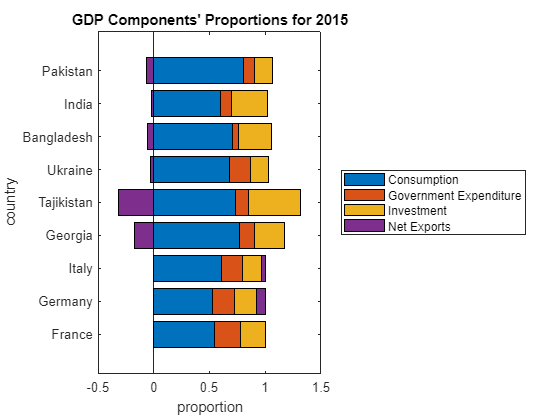

% create matrix of proportions to be used for stacked bar chart
bar_matrix = [table2array(tempdata5(1:4, 4)).' ./ sum(tempdata5.("2015")(1:4), 1);
              table2array(tempdata5(5:8, 4)).' ./ sum(tempdata5.("2015")(5:8), 1);
              table2array(tempdata5(9:12, 4)).' ./ sum(tempdata5.("2015")(9:12), 1);
              table2array(tempdata6(1:4, 4)).' ./ sum(tempdata6.("2015")(1:4), 1);
              table2array(tempdata6(5:8, 4)).' ./ sum(tempdata6.("2015")(5:8), 1);
              table2array(tempdata6(9:12, 4)).' ./ sum(tempdata6.("2015")(9:12), 1);
              table2array(tempdata7(1:4, 4)).' ./ sum(tempdata7.("2015")(1:4), 1);
              table2array(tempdata7(5:8, 4)).' ./ sum(tempdata7.("2015")(5:8), 1);
              table2array(tempdata7(9:12, 4)).' ./ sum(tempdata7.("2015")(9:12), 1)];

% plot the stacked bar chart
bar(bar_matrix, 'stacked', 'Horizontal','on');
title('GDP Components'' Proportions for 2015');
xlabel('proportion');
ylabel('country');
yticklabels({'France', 'Germany', 'Italy', 'Georgia', 'Tajikistan', 'Ukraine', 'Bangladesh', 'India', 'Pakistan'});
legend('Consumption', 'Government Expenditure', 'Investment', 'Net Exports', 'Location', 'eastoutside');

## **PART 4.2:**

% start fresh
clc, clearvars, close all

% import and format data set
tempdata8 = readtable('HDR21-22_Statistical_Annex_HDI_Table.xlsx', Sheet = 'Table 1' ,ReadVariableNames = false, VariableNamingRule = 'preserve', TextType='string', Range='A9:O202');
tempdata8 = tempdata8(~isnan(tempdata8.Var1), [1 2 3 5 7 9 11 13 15]);
tempdata8.Properties.VariableNames = {'hdi_rank_2021', 'country', 'hdi_value', 'life_exp_years', 'exp_years_school', 'mean_years_school', 'gni_capita', 'gni_hdi_rank', 'hdi_rank_2020'};
tempdata8.hdi_value = round(tempdata8.hdi_value, 3);
tempdata8.life_exp_years = round(tempdata8.life_exp_years, 1);
tempdata8.exp_years_school = round(tempdata8.exp_years_school, 1);
tempdata8.mean_years_school = round(tempdata8.mean_years_school, 1);
tempdata8

tempdata8 = 191×9 table
    hdi_rank_2021            country             hdi_value    life_exp_years    exp_years_school    mean_years_school    gni_capita    gni_hdi_rank    hdi_rank_2020
    _____________    ________________________    _________    ______________    ________________    _________________    __________    ____________    _____________

          1          "Switzerland"                 0.962             84               16.5                13.9                66933          5               3      
          2          "Norway"                      0.961           83.2               18.2                  13                64660          6               1      
         

% calculate health index
health_idx = (tempdata8.life_exp_years - 20) / (85 - 20);

% calculate education index
exp_school = min([tempdata8.exp_years_school / 18 ones(191, 1)].').';
mean_school = tempdata8.mean_years_school / 15;
edu_idx = (exp_school + mean_school) / 2;

% calculate income index
inc_idx = (log(tempdata8.gni_capita) - log(100)) / (log(75000) - log(100));

% calculate hdi
hdi = round((health_idx .* edu_idx .* inc_idx).^(1/3), 3);
hdi.'

ans =     0.9630    0.9610    0.9600    0.9550    0.9500    0.9480    0.9470    0.9460    0.9420    0.9420    0.9400    0.9470    0.9370    0.9370    0.9360    0.9650    0.9350    0.9280    0.9250    0.9240    0.9220    0.9190    0.9170    0.9190    0.9160    0.9110    0.9050    0.9020    0.8950    0.8940    0.8890    0.8890    0.8870    0.8770    0.8750    0.8750    0.8740    0.8660    0.8640    0.8590    0.8580    0.8540    0.8610    0.8540    0.8470    0.8450    0.8420    0.8370    0.8330    0.8300
